clc; clear all; close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

%for u = 1:height(T)
    k=3

k = 3


% Leer la imagen original
image = imread(string(fullfile(img_path, T{k,1})));

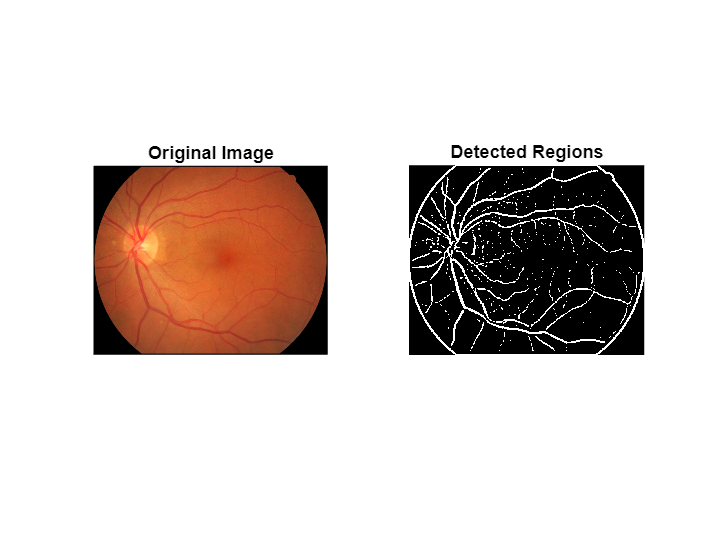



% Step 2: Convert to grayscale
grayImage = rgb2gray(image);

% Step 3: Apply GLoG filter
filterSize = 100; % Adjust the filter size as needed
sigma = 2; % Adjust the sigma value as needed
filter = fspecial('log', filterSize, sigma);
grayImage = imresize(grayImage, [NaN, 600], 'bicubic');
filteredImage = imfilter(grayImage, filter, 'same');

% Step 4: Threshold the filtered image
threshold = 0.5; % Adjust the threshold value as needed
binaryImage = filteredImage > threshold;
% Step 5: Display the results
figure;
subplot(1, 2, 1);
imshow(image);
title('Original Image');
subplot(1, 2, 2);
imshow(binaryImage);
title('Detected Regions');